bass = matfile('data_bass.mat')

bass =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\data_bass.mat'
            Properties.Writable: false                                                           
    Properties.ProtectedLoading: false                                                           
                    circularity: [1x15 double]                                                   
                    compactness: [1x15 double]                                                   
                     elongation: [1x15 double]                                                   
                          holes: [1x15 int32]                                                    
                      intensity: [1x15 double]                                                   
                        thiness: [1x15 double]                                                   

  

guitar = matfile('data_guitar.mat')

guitar =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\data_guitar.mat'
            Properties.Writable: false                                                             
    Properties.ProtectedLoading: false                                                             
                    circularity: [1x15 double]                                                     
                    compactness: [1x15 double]                                                     
                     elongation: [1x15 double]                                                     
                          holes: [1x15 int32]                                                      
                      intensity: [1x15 double]                                                     
                        thiness: [1x15 double]                                                     

  <a href="

trumpet = matfile('data_trumpet.mat')

trumpet =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\data_trumpet.mat'
            Properties.Writable: false                                                              
    Properties.ProtectedLoading: false                                                              
                    circularity: [1x15 double]                                                      
                    compactness: [1x15 double]                                                      
                     elongation: [1x15 double]                                                      
                          holes: [1x15 int32]                                                       
                      intensity: [1x15 double]                                                      
                        thiness: [1x15 double]                                                      

 

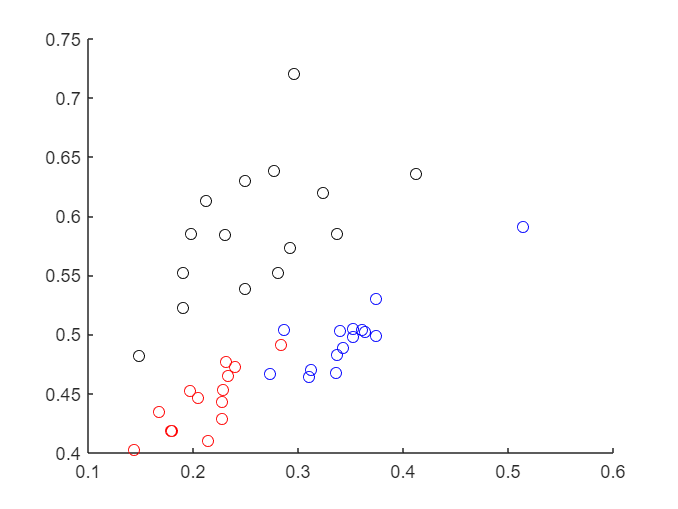


scatter(bass.circularity,bass.compactness,'red')
hold on
scatter(guitar.circularity,guitar.compactness,'blue')
scatter(trumpet.circularity,trumpet.compactness,'black')
hold off

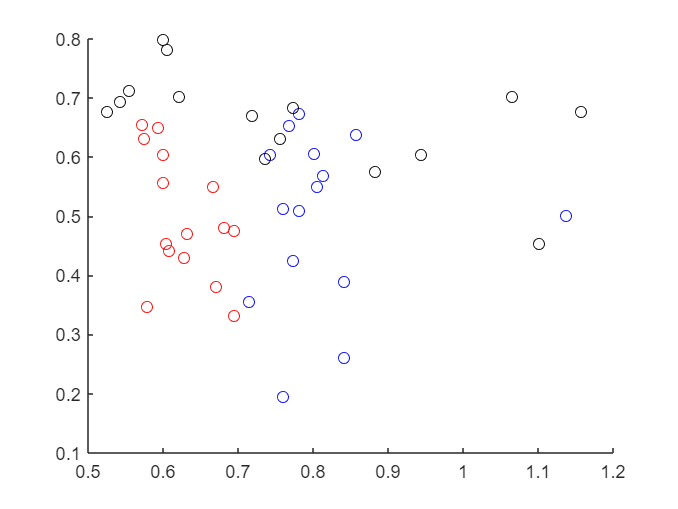


scatter(bass.elongation,bass.intensity,'red')
hold on
scatter(guitar.elongation,guitar.intensity,'blue')
scatter(trumpet.elongation,trumpet.intensity,'black')
hold off

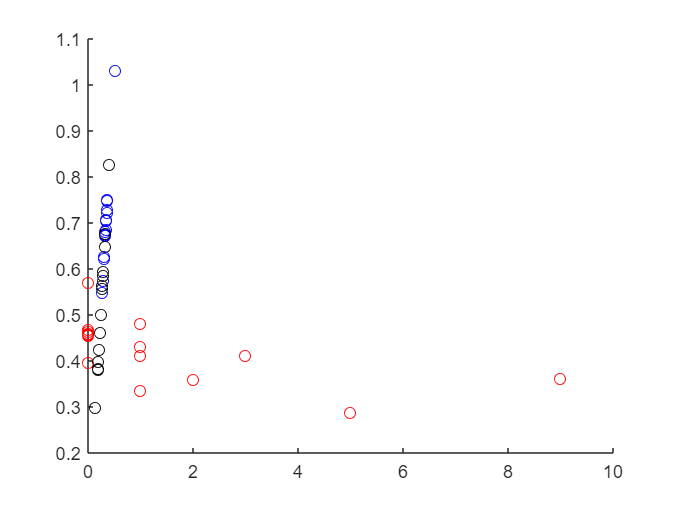


scatter(bass.holes,bass.thiness,'red')
hold on
scatter(guitar.circularity,guitar.thiness,'blue')
scatter(trumpet.circularity,trumpet.thiness,'black')
hold off

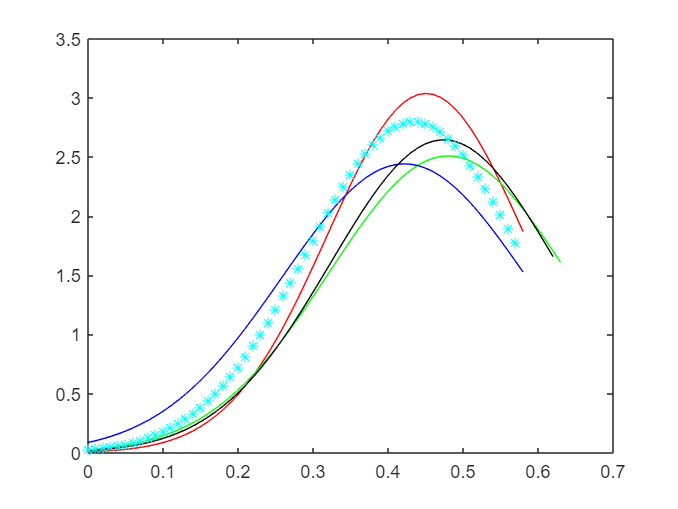


meanData=mean([bass.circularity; bass.compactness; bass.elongation; bass.intensity; bass.thiness]);
sigma1=sqrt(var([bass.circularity; bass.compactness; bass.elongation; bass.intensity; bass.thiness]));
xA=[0:0.01:1*sigma1(1)+meanData(1)];
yA=normpdf(xA,meanData(1),sigma1(1));
xB=[0:0.01:1*sigma1(2)+meanData(2)];
yB=normpdf(xB,meanData(2),sigma1(2));
xC=[0:0.01:1*sigma1(3)+meanData(3)];
yC=normpdf(xC,meanData(3),sigma1(3));
xD=[0:0.01:1*sigma1(4)+meanData(4)];
yD=normpdf(xD,meanData(4),sigma1(4));
xE=[0:0.01:1*sigma1(5)+meanData(5)];
yE=normpdf(xE,meanData(5),sigma1(5));

plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
plot(xE, yE, 'c*')
hold off

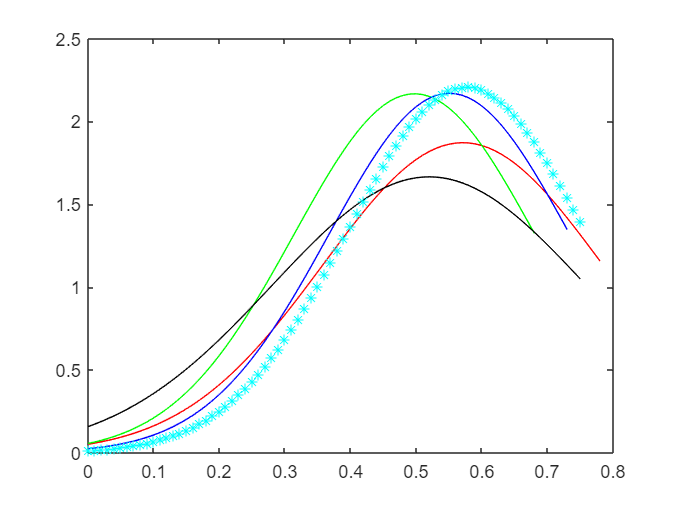


meanData=mean([guitar.circularity; guitar.compactness; guitar.elongation; guitar.intensity; guitar.thiness]);
sigma1=sqrt(var([guitar.circularity; guitar.compactness; guitar.elongation; guitar.intensity; guitar.thiness]));
xA=[0:0.01:1*sigma1(1)+meanData(1)];
yA=normpdf(xA,meanData(1),sigma1(1));
xB=[0:0.01:1*sigma1(2)+meanData(2)];
yB=normpdf(xB,meanData(2),sigma1(2));
xC=[0:0.01:1*sigma1(3)+meanData(3)];
yC=normpdf(xC,meanData(3),sigma1(3));
xD=[0:0.01:1*sigma1(4)+meanData(4)];
yD=normpdf(xD,meanData(4),sigma1(4));
xE=[0:0.01:1*sigma1(5)+meanData(5)];
yE=normpdf(xE,meanData(5),sigma1(5));

plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
plot(xE, yE, 'c*')
hold off

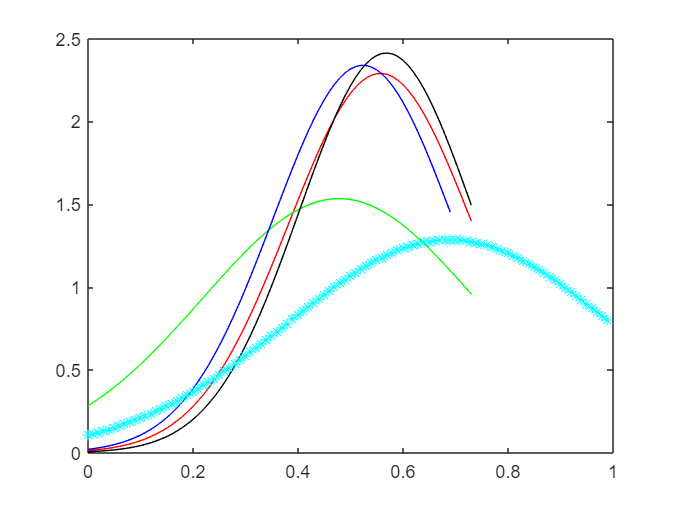


meanData=mean([trumpet.circularity; trumpet.compactness; trumpet.elongation; trumpet.intensity; trumpet.thiness]);
sigma1=sqrt(var([trumpet.circularity; trumpet.compactness; trumpet.elongation; trumpet.intensity; trumpet.thiness]));
xA=[0:0.01:1*sigma1(1)+meanData(1)];
yA=normpdf(xA,meanData(1),sigma1(1));
xB=[0:0.01:1*sigma1(2)+meanData(2)];
yB=normpdf(xB,meanData(2),sigma1(2));
xC=[0:0.01:1*sigma1(3)+meanData(3)];
yC=normpdf(xC,meanData(3),sigma1(3));
xD=[0:0.01:1*sigma1(4)+meanData(4)];
yD=normpdf(xD,meanData(4),sigma1(4));
xE=[0:0.01:1*sigma1(5)+meanData(5)];
yE=normpdf(xE,meanData(5),sigma1(5));

plot(xA,yA,'red')
hold on
plot(xB,yB,'green')
plot(xC,yC,'blue')
plot(xD,yD,'black')
plot(xE, yE, 'c*')
hold off